random numbers distributed according to a

standard normal distribution using the Box-Muller algorithm.

u1 = rand();
u2 = rand();

x1 = (- 2 * log(u1)) * cos( 2* pi * u2)

x1 = 0.3401

x2 = (- 2 * log(u1)) * sin( 2* pi * u2)

x2 = -0.2287

random numbers distributed according to a

Gaussian distribution with mean 6 and standard deviation 8.

u1 = rand();
u2 = rand();
x1 = (- 2 * log(u1)) * cos( 2* pi * u2)

x1 = 3.5310

x2 = (- 2 * log(u1)) * sin( 2* pi * u2)

x2 = -2.1371


mu = 6;
sigma = 8;
y1 = mu + sigma * x1

y1 = 34.2476

y2 = mu + sigma * x2

y2 = -11.0971

Generate 1000 random numbers distributed according to a

**normal distribution** with mean 6 and standard deviation 8. Plot the

**PDF** and the random numbers.

N = 1000; % Number of random numbers to generate
mu = 6;
sigma = 8;
% Generate random numbers
randomnumbers = normrnd(mu, sigma, [1, N]);
figure;
histogram(randomnumbers, 'Normalization', 'pdf', 'EdgeColor', 'none');
hold on;
% Define the range of x values for plotting the Gaussian PDF
x = linspace(min(randomnumbers), max(randomnumbers), 100);

pdf = (1/(sigma * sqrt(2 * pi))) * exp(-0.5 * ((x - mu) / sigma).^2);

plot(x, pdf, 'r', 'LineWidth', 2);
grid on;

If we want to generate more gaussian random numbers with** Box-Muller**

**algorithm**, we can use the following code.

close all
N = 100;

    if N <= 0
        error('N must be positive integer');
    end

numpairs = ceil(N/2);
z = zeros(1,N);

    for i=1:numpairs
        u1 = rand();
        u2 = rand();
        z1 = sqrt(- 2 * log(u1)) * cos(2 * pi * u2);
        z2 = sqrt(- 2 * log(u1)) * sin(2 * pi * u2);
        z(2*i-1) = z1;
        if 2*i <= N
            z(2*i) = z2;
        end
    end

        if mod(N, 2) == 1
            z = z(1:N);
        end
        
disp(z)

    0.3989    0.8562   -0.4177   -2.4547   -0.7744   -1.2307   -0.9640   -0.9928    2.3430   -1.4751   -0.0174   -0.6668   -0.4780    0.4305   -0.8738   -0.4487   -0.1767    1.1128   -1.5920    0.4992    0.5771   -1.6206    0.1643    0.0313    0.9543    0.5813    0.6626   -0.0453    2.1589   -0.8642   -1.1433   -2.5900   -0.6821   -0.1486    0.3974   -0.2926    0.6270    0.7375    0.7221    1.5896    1.9719    1.5685    0.9138   -0.3641   -1.2191    0.7669    0.1673   -0.0596    0.8815   -0.0649   -0.3776    0.6232    0.0333    0.9070   -0.6632   -1.4136   -0.9605    0.5961    0.0033   -1.0064   -0.9835   -0.3318   -1.0350   -0.0770   -0.4244   -2.1926   -0.0536    0.0695   -0.1376    0.1985   -0.4710    0.1378    0.2676    1.3019   -0.7369    1.8988    0.1641   -0.7831    0.8535    0.0526    0.5158   -0.2738    0.6955    0.1910   -0.3946   -1.3375    0.1278    0.7839   -0.7534   -1.4346   -0.8667   -0.8528    0.7507    1.5233    0.0649   -0.6077    0.2868    0.2309    1.4990    1.0761

sample of 1000 random numbers from the **exponential**

**distribution f= e^(-x)** using the** inverse cumulative method**. Then plot

the histogram and the function.

pdf = @(x) exp(-x); 

cdf_inv = @(u) -log(1 - u); % Inverse CDF for the exponential distribution
sample = 1000; % Number of random numbers to generate
randomnumbers = cdf_inv(rand(1, sample));
figure;
histogram(randomnumbers, 'Normalization', 'pdf', 'EdgeColor', 'none');
hold on;
x = linspace(0, 10, 100);
plot(x, pdf(x), 'r', 'LineWidth', 2);
% Add labels and title
xlabel('Value');
ylabel('Probability Density');
title('Histogram of Random Numbers and Probability Density Function');
legend('Histogram of random numbers', 'PDF');
grid on;
hold off;

10^4 random numbers according to a **normalized**

**histogram** in the interval [0,5]

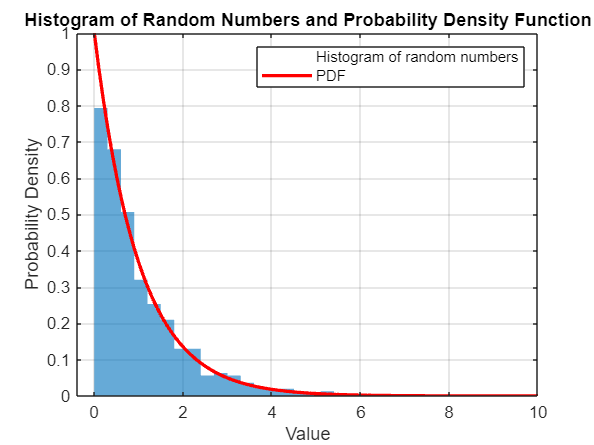

% Define histogram bin edges
binedges = linspace(0,5,6);
% Define the normalized probabilities for each bin
probabilities = [0.1, 0.2, 0.4, 0.2, 0.1];
% Validate that the probabilities sum to 1

    if abs(sum(probabilities) - 1) > 1e-6
        error('Probabilities must sum to 1.');
    end
% Create the cumulative distribution function (CDF)
cdf = cumsum(probabilities);

n = 1e4;
% Generate uniform random numbers in the range [0, 1]
u = rand(n, 1);
% Initialize the array for random numbers according to the histogram
randomnumbers = zeros(n, 1);
% Inverse transform sampling
    for i = 1:n
% Find the corresponding bin for each uniform random number
         binindex = find(u(i) <= cdf, 1, 'first');
% Generate a random number within the bin
         randomnumbers(i) = binedges(binindex) + (binedges(binindex + 1) -binedges(binindex)) * rand();
    end

figure;
histogram(randomnumbers, 'binedges', binedges, 'Normalization', 'probability');
xlabel('Value');
ylabel('Probability');

Generate 10^4 random numbers distributed according to the

probability density f=x^2 in [0 5] . Create an histogram of the

samples and compute the mean and variance

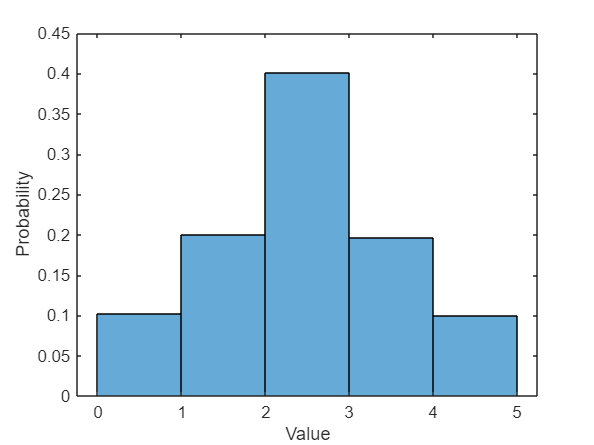

clear all
close all

a = 0;

b = 5;
n = 1e4;

p_x = @(x) x.^2;

p_max = 25;
h = 36;

samples = zeros(1, n);
count = 0;

    while count < n
        x = a + (b-a) * rand;
        p_value = p_x(x);
        y = h * rand;

        if y <= p_value
            count = count + 1;
            samples(count) = x;
        end

    end
    
expectation_value = mean(samples)

var_value = var(samples)

histogram(samples, 'Normalization', 'pdf');
hold on;

z = linspace(0, 5, 100);


expectation_value = 3.7562

pdf = (3/125)* z.^2;


var_value = 0.9306

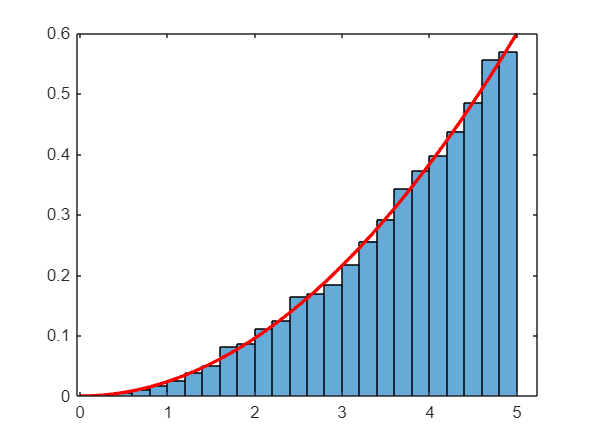

plot(z, pdf, 'r', 'LineWidth', 2);
hold off;
